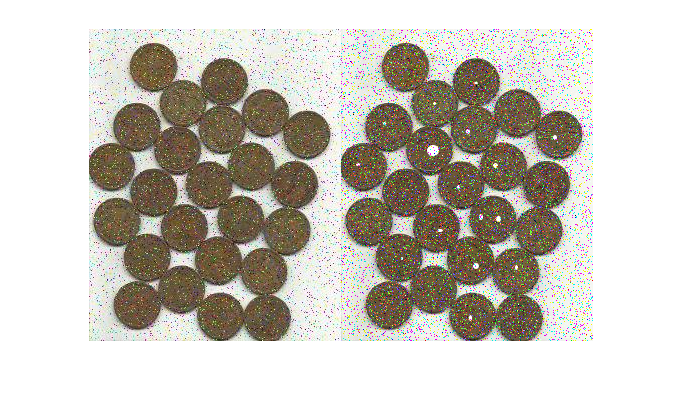

% T = graythresh(I) computes a global threshold T from grayscale
% image I, using Otsu's method [1]. Otsu's method chooses a threshold
% that minimizes the intraclass variance of the thresholded black and
% white pixels. The global threshold T can be used with imbinarize to
% convert a grayscale image to a binary image.

im = imread("D:\Projects\computer-vision\Lab 5\corrupted_coins.jpg");
imP = Process2(im);

im2 = imread("D:\Projects\computer-vision\Lab 5\holes_corrupted_coins.png");
imP2 = Process2(im2);

imshowpair(im, im2, 'montage')

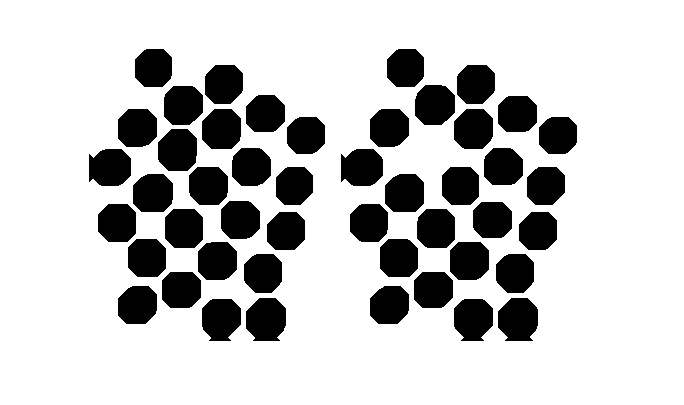

imshowpair(imP, imP2, 'montage')

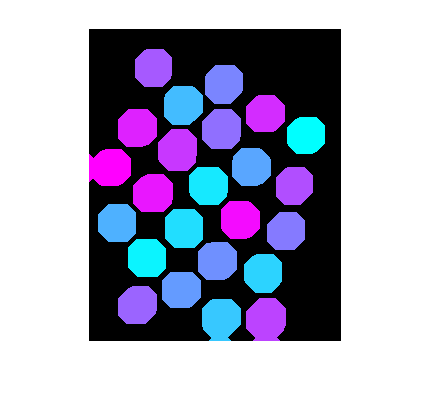


CC = bwconncomp(~imP);
L = labelmatrix(CC);
RGB = label2rgb(L,'cool','k','shuffle'); 
imshow(RGB)

regionprops("table",CC,"all")

ans = 24×30 table
    Area        Centroid                  BoundingBox                        SubarrayIdx              MajorAxisLength    MinorAxisLength    Eccentricity    Orientation      ConvexHull        ConvexImage      ConvexArea    Circularity         Image           FilledImage      FilledArea    EulerNumber      Extrema       EquivDiameter    Solidity    Extent      PixelIdxList         PixelList       Perimeter    PerimeterOld    MaxFeretDiameter    MaxFeretAngle    MaxFeretCoordinates    MinFeretDiameter   


% DRAW BOUNDING BOXES AND GET BLOB COUNT
disp(CC.NumObjects + " objects detected")

24 objects detected


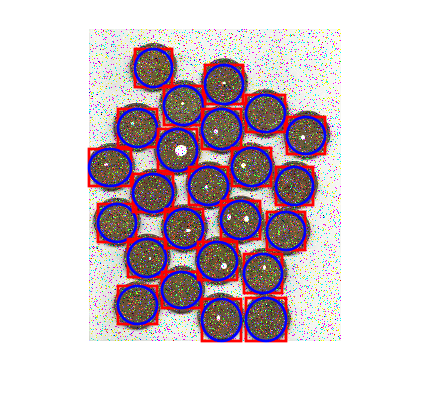

info = regionprops(CC,'Boundingbox') ;
imshow(im2)
% hold on
for k = 1 : length(info)
     BB = info(k).BoundingBox;
     rectangle('Position', [BB(1),BB(2),BB(3),BB(4)],'EdgeColor','r','LineWidth',2) ;
     rectangle('Position', [BB(1),BB(2),BB(3),BB(4)],'EdgeColor','b','LineWidth',2,"Curvature",[1,1]) ;
end

function imP = Process1(im)
    % Convert to greyscale
    imP = rgb2gray(im);    

    % Apply gaussian blur
    imP = medfilt2(imP);

    % Otsu's Graythresh
    level = graythresh(imP);
    imP = imbinarize(imP,level);
    
    % Morphological ops
    imP = imfill(imP, 'holes');
    
    % Morphological ops
    se = strel('disk',22);
    imP = imclose(imP, se);
    
    se = strel('disk',2);
    imP = imdilate(imP, se);
    
    se = strel('disk',19);
    imP = imclose(imP, se);
    
    se = strel('disk',2);
    imP = imdilate(imP, se);
    
%     imP = imgaussfilt(double(imP), 3);
    
end

function imP = Process2(im)
    % Convert to greyscale
    imP = rgb2gray(im);
    imP = imgaussfilt(imP, 0.47);
    imP = medfilt2(imP);

    % https://uk.mathworks.com/help/images/noise-removal.html
    imP = filter2(fspecial('average',5),imP)/255;
    
    imP = imfill(imP, 'holes');
    % Morphological ops
    se = strel('line',6,200);
    imP = imerode(imP, se);
    
    % Otsu's Graythresh
    level = graythresh(imP);
    imP = imbinarize(imP,level);
    
    % Morphological ops
    se = strel('diamond', 6);
    imP = imdilate(imP, se);
    
    se = strel('disk',17);
    imP = imclose(imP, se);
    
end

function imP = Process3(im)
    % Convert to greyscale
    imP = rgb2gray(im);
    imP = imgaussfilt(imP, 0.47);
    imP = medfilt2(imP);

    % https://uk.mathworks.com/help/images/noise-removal.html
    imP = filter2(fspecial('average',5),imP)/255;
    
    imP = imfill(imP, 'holes');
    imP = histeq(imP);
end